# Trabajo practico integrador

 

#### Evolucion de la temperatura a lo largo de la barra de acero en el tiempo

T = importdata('TempMed.mat');
n = length(T(:,1));
x = 0:0.05:1;

for i = 1:n
    plot(x,T(i,:),'r*')
    title(sprintf('Temperatura en el min %d',i-1))
    xlabel('Coordenada x (m)')
    ylabel('Temperatura (°C)')
    grid on
    ylim([500 1500])
    pause(1 -0.6)
end



#### Temperatura promedio de la barra en el tiempo

T = importdata('TempMed.mat');
n = length(T(:,1));
x = 0:0.05:1;
t = 0:60:3600;

[xx,tt] = meshgrid(x,t);
clf
for i = 1:n
    TemperaturaPromedio = promedio(T(i,:));
    hold on
    plot(i,TemperaturaPromedio,'bo')
    xlabel('Tiempo transcurrido (min)')
    ylabel('Temperatura promedio (°C)')
    hold off
end

#### Grafico de la temperatura [°C] en funcion del tiempo [s] y el largo de la barra [m]

surf(xx,tt,T)
xlabel('cordenada x (m)')
ylabel('Tiempo transcurrido (s)')
zlabel('Temperatura (°C)')

## Ajuste discreto

A diferencia de un ajuste lineal, donde la funcion de ajuste es la ecuacion de una recta, o en el caso de dos variables, de un plano $\mathrm{F}\left(x,y\right)=\beta_{0\;} +\beta_1 *x_i \;+\beta_2 *\textrm{yi}\;$ , se propone la función de ajuste: $T\left(x,t\right)=c_1 +400\cos \left(c_2 x\right)e^{-\lambda 4\pi 2t} +100\cos \left(\frac{4\pi *x}{L}\right)e^{-c_3 t} \;\left\lbrack \textrm{◦C}\right\rbrack$ que predice la temperatura a lo largo de la barra para cada instante de tiempo, pero se desconocen las constantes $c_1 ,c_2 \;y\;c_3$

Se buscaran valores para $$c_1 ,c_2 \;y\;c_3$$ que minimicen el error cuadratico medio (ECM).


$$\textrm{ECM}=\frac{\sum_{i\;=\;1}^{61} \sum_{j\;=\;1}^{21} {\left\lbrack {\mathbf{T}}_{i,j} -\mathbf{T}\left(x_j ,t_i ,c_1 ,c_2 ,c_3 \right)\right\rbrack }^2 }{61*21}=\sum_{i\;=\;1}^{61} \sum_{j\;=\;1}^{21} \frac{\left\lbrack {\mathrm{T}}_{i,j} -c_1 -400\cos \left(c_2 x_j \right)*e^{-\lambda 4\pi^2 t_i } -100\cos \left(\frac{4\pi *x_j }{L}\right)*e^{-c_3 t_i } \right\rbrack }{1281}$$


Los $$c_1 ,c_2 \;y\;c_3$$ que minimicen el ECM, seran los que satisfagan el siguiente sistema de ecuaciones:


$$f_1 \;=\;\frac{\partial }{\partial c_1 }\textrm{ECM}\;=\sum_{i\;=\;1}^{61} \sum_{j\;=\;1}^{21} \frac{-2*\left\lbrack {\mathrm{T}}_{i,j} -c_1 -400\cos \left(c_2 x_j \right)*e^{-\lambda 4\pi^2 t_i } -100\cos \left(\frac{4\pi *x_j }{L}\right)*e^{-c_3 t_i } \right\rbrack }{1281}=0$$



$$f_2 \;=\;\frac{\partial }{\partial c_2 }\textrm{ECM}\;=\sum_{i\;=\;1}^{61} \sum_{j\;=\;1}^{21} \frac{800x_j *\textrm{sen}\left(c_2 x_j \right)*e^{-\lambda 4\pi^2 t_i } *\left\lbrack {\mathrm{T}}_{i,j} -c_1 -400\cos \left(c_2 x_j \right)*e^{-\lambda 4\pi^2 t_i } -100\cos \left(\frac{4\pi *x_j }{L}\right)*e^{-c_3 t_i } \right\rbrack }{1281}=0$$



$$f_3 \;=\;\frac{\partial }{\partial c_3 }\textrm{ECM}\;=\sum_{i\;=\;1}^{61} \sum_{j\;=\;1}^{21} \frac{200t_i *\cos \left(\frac{4\pi *x_j }{L}\right)*e^{-c_3 t_i } *\left\lbrack {\mathrm{T}}_{i,j} -c_1 -400\cos \left(c_2 x_j \right)*e^{-\lambda 4\pi^2 t_i } -100\cos \left(\frac{4\pi *x_j }{L}\right)*e^{-c_3 t_i } \right\rbrack }{1281}=0$$


Este sistema de ecuaciones no lineales se puede resolver mediante el método de Newton Raphson para sistemas de ecuaciones de la siguiente manera:


$$\left\lbrack \begin{array}{c}
c_{1,k+1} \\
c_{2,k+1} \\
c_{3,k+1} 
\end{array}\right\rbrack \approx \left\lbrack \begin{array}{c}
c_{1,k} \\
c_{2,k} \\
c_{3,k} 
\end{array}\right\rbrack -\Delta C$$



$$\;\Delta C=\;\left\lbrack \begin{array}{ccc}
\frac{\partial }{\partial c_1 }f_1 |_{\left(c_{1,k} ,c_{2,k} ,c_{3,k} \right)}  & \frac{\partial }{\partial c_2 }f_1 |_{\left(c_{1,k} ,c_{2,k} ,c_{3,k} \right)}  & \frac{\partial }{\partial c_3 }f_1 |_{\left(c_{1,k} ,c_{2,k} ,c_{3,k} \right)} \\
\frac{\partial }{\partial c_1 }f_2 |_{\left(c_{1,k} ,c_{2,k} ,c_{3,k} \right)}  & \frac{\partial }{\partial c_2 }f_2 |_{\left(c_{1,k} ,c_{2,k} ,c_{3,k} \right)}  & \frac{\partial }{\partial c_3 }f_2 |_{\left(c_{1,k} ,c_{2,k} ,c_{3,k} \right)} \\
\frac{\partial }{\partial c_1 }f_3 |_{\left(c_{1,k} ,c_{2,k} ,c_{3,k} \right)}  & \frac{\partial }{\partial c_2 }f_3 |_{\left(c_{1,k} ,c_{2,k} ,c_{3,k} \right)}  & \frac{\partial }{\partial c_3 }f_3 |_{\left(c_{1,k} ,c_{2,k} ,c_{3,k} \right)} 
\end{array}\right\rbrack *\left\lbrack \begin{array}{c}
f_1 \left(c_{1,k} ,c_{2,k} ,c_{3,k} \right)\\
f_2 \left(c_{1,k} ,c_{2,k} ,c_{3,k} \right)\\
f_3 \left(c_{1,k} ,c_{2,k} ,c_{3,k} \right)
\end{array}\right\rbrack$$


La forma de calcular una derivada parcial numericamente es:


$$\frac{\partial }{\partial x_j }f_i \approx \frac{f_i \left(x_1 ,\ldotp \ldotp \ldotp ,x_j +\sigma x_j ,\ldotp \ldotp \ldotp ,x_n \right)-f_i \left(x_1 ,\ldotp \ldotp \ldotp ,x_j ,\ldotp \ldotp \ldotp ,x_n \right)}{\sigma x_j }$$


donde $\sigma x_j$ es un valor pequeño elegido arbitrariamente

Además es bueno tener buenas aproccimaciones iniciales, Para esto se puede probar con distintos valores de $c_1 ,c_2 \;\mathrm{y}\;c_3$ hasta que la función $T\left(x,t\right)=c_1 +400\cos \left(c_2 x\right)*e^{-\lambda 4\pi 2t} +100\cos \left(\frac{4\pi *x}{L}\right)*e^{-c_3 t} \;\left\lbrack \textrm{◦C}\right\rbrack$ aproxime los datos obtenidos empiricamente.

clear all

T = importdata('TempMed.mat');
n = length(T(:,1));
x = 0:0.05:1;
t = 0:60:3600;
L = 1;
alfa = 22.8*10^(-6);
lamda = alfa/L^2;

c1 =900;
c2 =999;
c3 = 0.16;

Temp = @(x,t) c1 + 400.*cos(c2.*x).*exp(-lamda.*4.*t.*pi.^2) + 100.*cos(4.*pi.*x./L).*exp(-c3.*t);

% for i = 1:length(t)
%     hold on
%     plot(x,Temp(x,t(i)))
%     plot(x,T(i,:),'r*')
%     ylim([500 1500])
%     hold off
%     pause(0)
%     if i ~= length(t)
%         clf
%     end    
% end

t = 0:60:3600;
J = zeros(3); % inicialización de la matriz de jacobianos
F = zeros(3,1); % inicialización del vector de funciones

dc1 = 0.01;
dc2 = 0.01;
dc3 = 0.01;
Contador = 0;
    c1k = inf;
    c2k = inf;
    c3k = inf;
Tol = 0.0002; NMax = 200;
%while any(abs(F) >= Tol) && Contador < NMax
 
while (abs((c1-c1k)/c1) >= Tol || abs((c2-c2k)/c2) >= Tol || abs((c3-c3k)/c3) >= Tol) && Contador < NMax 
    for i = 1:61
        for j = 1:21

            % Terminos generales de las sumatorias
            f1 = @(c1,c2,c3) ((-2*(T(i,j) - c1 - 400*cos(c2*x(j))*exp(-lamda*pi^2*4*t(i)) - 100*cos(4*pi*x(j)/L)*exp(-c3*t(i))))/1281);
            f2 = @(c1,c2,c3) (800*x(j).*exp(-lamda*pi^2*4*t(i))*sin(c2*x(j))*(T(i,j) - c1 - 400*cos(c2*x(j))*exp(-lamda*pi^2*4*t(i)) - 100*cos(4*pi*x(j)/L)*exp(-c3*t(i))))/1281;
            f3 = @(c1,c2,c3) (200*t(i)*cos(4*pi*x(j)/L)*exp(-c3*t(i))*(T(i,j) - c1 - 400*cos(c2*x(j))*exp(-lamda*pi^2*4*t(i)) - 100*cos(4*pi*x(j)/L)*exp(-c3*t(i))))/1281;

            %%%%%%%%%%%%%%%%% Matriz de jacobianos %%%%%%%%%%%%%%%%%%%
            J(1,1) = J(1,1) + (f1(c1 + dc1,c2,c3) - f1(c1,c2,c3))/dc1;
            J(1,2) = J(1,2) + (f1(c1,c2 + dc2,c3) - f1(c1,c2,c3))/dc2;
            J(1,3) = J(1,3) + (f1(c1,c2,c3 + dc3) - f1(c1,c2,c3))/dc3;
            J(2,1) = J(2,1) + (f2(c1 + dc1,c2,c3) - f2(c1,c2,c3))/dc1;
            J(2,2) = J(2,2) + (f2(c1,c2 + dc2,c3) - f2(c1,c2,c3))/dc2;
            J(2,3) = J(2,3) + (f2(c1,c2,c3 + dc3) - f2(c1,c2,c3))/dc3;
            J(3,1) = J(3,1) + (f3(c1 + dc1,c2,c3) - f3(c1,c2,c3))/dc1;
            J(3,2) = J(3,2) + (f3(c1,c2 + dc2,c3) - f3(c1,c2,c3))/dc2;
            J(3,3) = J(3,3) + (f3(c1,c2,c3 + dc3) - f3(c1,c2,c3))/dc3;
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
            %%% Vector de funciones %%%
            F(1) = F(1) + f1(c1,c2,c3);
            F(2) = F(2) + f2(c1,c2,c3);
            F(3) = F(3) + f3(c1,c2,c3);
            %%%%%%%%%%%%%%%%%%%%%%%%%%%
        end
    end 

    fprintf('########## Inicio de la iteracion %d ##########',Contador + 1)
    J
    F;
    dC = J\F;
    c1k = c1;
    c2k = c2;
    c3k = c3;
    c1 = c1 - dC(1);
    c2 = c2 - dC(2);
    c3 = c3 - dC(3);
    dc1 = c1 -c1k;
    dc2 = c2 - c2k;
    dc3 = c3 -c3k;
    Contador = Contador + 1;
    fprintf('##############################################')

    VectorC1(Contador) = c1;
    VectorC2(Contador) = c2;
    VectorC3(Contador) = c3;
    VectorContador(Contador) = Contador;
end

########## Inicio de la iteracion 1 ##########

J = 1.0e+03 *

    0.0020   -0.0357   -0.0000
   -0.0356    7.9432   -0.0002
   -0.0000   -0.0003   -0.0237


##############################################

########## Inicio de la iteracion 2 ##########

J = 1.0e+04 *

    0.0004   -0.0073   -0.0000
   -0.0072    1.6288   -0.0000
   -0.0000   -0.0000   -0.0028


##############################################

########## Inicio de la iteracion 3 ##########

J = 1.0e+04 *

    0.0006   -0.0110   -0.0000
   -0.0109    2.4692   -0.0000
   -0.0000   -0.0000   -0.0030


##############################################

########## Inicio de la iteracion 4 ##########

J = 1.0e+04 *

    0.0008   -0.0147   -0.0000
   -0.0146    3.3090   -0.0000
   -0.0000   -0.0000   -0.0030


##############################################

########## Inicio de la iteracion 5 ##########

J = 1.0e+04 *

    0.0010   -0.0184   -0.0000
   -0.0183    4.1443   -0.0000
   -0.0000   -0.0000   -0.0030


##############################################

########## Inicio de la iteracion 6 ##########

J = 1.0e+04 *

    0.0012   -0.0221   -0.0000
   -0.0220    4.9735   -0.0000
   -0.0000   -0.0000   -0.0030


##############################################

########## Inicio de la iteracion 7 ##########

J = 1.0e+04 *

    0.0014   -0.0258   -0.0000
   -0.0257    5.7961   -0.0000
   -0.0000   -0.0000   -0.0030


##############################################

########## Inicio de la iteracion 8 ##########

J = 1.0e+04 *

    0.0016   -0.0294   -0.0000
   -0.0294    6.6128   -0.0000
   -0.0000   -0.0000   -0.0030


##############################################

########## Inicio de la iteracion 9 ##########

J = 1.0e+04 *

    0.0018   -0.0330   -0.0000
   -0.0330    7.4245   -0.0000
   -0.0000   -0.0000   -0.0030


##############################################

########## Inicio de la iteracion 10 ##########

J = 1.0e+04 *

    0.0020   -0.0367   -0.0000
   -0.0366    8.2326   -0.0000
   -0.0000   -0.0000   -0.0030


##############################################

########## Inicio de la iteracion 11 ##########

J = 1.0e+04 *

    0.0022   -0.0403   -0.0000
   -0.0402    9.0386   -0.0000
   -0.0000   -0.0000   -0.0030


##############################################

########## Inicio de la iteracion 12 ##########

J = 1.0e+04 *

    0.0024   -0.0439   -0.0000
   -0.0439    9.8436   -0.0000
   -0.0000   -0.0000   -0.0030


##############################################

########## Inicio de la iteracion 13 ##########

J = 1.0e+05 *

    0.0003   -0.0047   -0.0000
   -0.0047    1.0649   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 14 ##########

J = 1.0e+05 *

    0.0003   -0.0051   -0.0000
   -0.0051    1.1455   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 15 ##########

J = 1.0e+05 *

    0.0003   -0.0055   -0.0000
   -0.0055    1.2264   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 16 ##########

J = 1.0e+05 *

    0.0003   -0.0058   -0.0000
   -0.0058    1.3075   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 17 ##########

J = 1.0e+05 *

    0.0003   -0.0062   -0.0000
   -0.0062    1.3889   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 18 ##########

J = 1.0e+05 *

    0.0004   -0.0066   -0.0000
   -0.0066    1.4706   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 19 ##########

J = 1.0e+05 *

    0.0004   -0.0069   -0.0000
   -0.0069    1.5525   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 20 ##########

J = 1.0e+05 *

    0.0004   -0.0073   -0.0000
   -0.0073    1.6348   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 21 ##########

J = 1.0e+05 *

    0.0004   -0.0077   -0.0000
   -0.0077    1.7173   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 22 ##########

J = 1.0e+05 *

    0.0004   -0.0080   -0.0000
   -0.0080    1.8000   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 23 ##########

J = 1.0e+05 *

    0.0005   -0.0084   -0.0000
   -0.0084    1.8829   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 24 ##########

J = 1.0e+05 *

    0.0005   -0.0088   -0.0000
   -0.0088    1.9658   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 25 ##########

J = 1.0e+05 *

    0.0005   -0.0091   -0.0000
   -0.0091    2.0489   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 26 ##########

J = 1.0e+05 *

    0.0005   -0.0095   -0.0000
   -0.0095    2.1319   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 27 ##########

J = 1.0e+05 *

    0.0005   -0.0099   -0.0000
   -0.0099    2.2150   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 28 ##########

J = 1.0e+05 *

    0.0006   -0.0102   -0.0000
   -0.0102    2.2979   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 29 ##########

J = 1.0e+05 *

    0.0006   -0.0106   -0.0000
   -0.0106    2.3808   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 30 ##########

J = 1.0e+05 *

    0.0006   -0.0110   -0.0000
   -0.0110    2.4635   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 31 ##########

J = 1.0e+05 *

    0.0006   -0.0113   -0.0000
   -0.0113    2.5461   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 32 ##########

J = 1.0e+05 *

    0.0006   -0.0117   -0.0000
   -0.0117    2.6285   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 33 ##########

J = 1.0e+05 *

    0.0007   -0.0121   -0.0000
   -0.0121    2.7107   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 34 ##########

J = 1.0e+05 *

    0.0007   -0.0124   -0.0000
   -0.0124    2.7927   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 35 ##########

J = 1.0e+05 *

    0.0007   -0.0128   -0.0000
   -0.0128    2.8746   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 36 ##########

J = 1.0e+05 *

    0.0007   -0.0132   -0.0000
   -0.0132    2.9562   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 37 ##########

J = 1.0e+05 *

    0.0007   -0.0135   -0.0000
   -0.0135    3.0377   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 38 ##########

J = 1.0e+05 *

    0.0008   -0.0139   -0.0000
   -0.0139    3.1191   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 39 ##########

J = 1.0e+05 *

    0.0008   -0.0143   -0.0000
   -0.0143    3.2003   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 40 ##########

J = 1.0e+05 *

    0.0008   -0.0146   -0.0000
   -0.0146    3.2815   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 41 ##########

J = 1.0e+05 *

    0.0008   -0.0150   -0.0000
   -0.0150    3.3625   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 42 ##########

J = 1.0e+05 *

    0.0008   -0.0154   -0.0000
   -0.0154    3.4435   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 43 ##########

J = 1.0e+05 *

    0.0009   -0.0157   -0.0000
   -0.0157    3.5244   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 44 ##########

J = 1.0e+05 *

    0.0009   -0.0161   -0.0000
   -0.0161    3.6053   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 45 ##########

J = 1.0e+05 *

    0.0009   -0.0164   -0.0000
   -0.0164    3.6862   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 46 ##########

J = 1.0e+05 *

    0.0009   -0.0168   -0.0000
   -0.0168    3.7671   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 47 ##########

J = 1.0e+05 *

    0.0009   -0.0172   -0.0000
   -0.0172    3.8481   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 48 ##########

J = 1.0e+05 *

    0.0010   -0.0175   -0.0000
   -0.0175    3.9292   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 49 ##########

J = 1.0e+05 *

    0.0010   -0.0179   -0.0000
   -0.0179    4.0103   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 50 ##########

J = 1.0e+05 *

    0.0010   -0.0183   -0.0000
   -0.0183    4.0915   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 51 ##########

J = 3×3
1.0e+05 *

    0.0010   -0.0186   -0.0000
   -0.0186    4.1728   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 52 ##########

J = 3×3
1.0e+05 *

    0.0010   -0.0190   -0.0000
   -0.0190    4.2543   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 53 ##########

J = 3×3
1.0e+05 *

    0.0011   -0.0194   -0.0000
   -0.0193    4.3358   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 54 ##########

J = 3×3
1.0e+05 *

    0.0011   -0.0197   -0.0000
   -0.0197    4.4175   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 55 ##########

J = 3×3
1.0e+05 *

    0.0011   -0.0201   -0.0000
   -0.0201    4.4993   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 56 ##########

J = 3×3
1.0e+05 *

    0.0011   -0.0204   -0.0000
   -0.0204    4.5812   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 57 ##########

J = 3×3
1.0e+05 *

    0.0011   -0.0208   -0.0000
   -0.0208    4.6633   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 58 ##########

J = 3×3
1.0e+05 *

    0.0012   -0.0212   -0.0000
   -0.0212    4.7455   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 59 ##########

J = 3×3
1.0e+05 *

    0.0012   -0.0215   -0.0000
   -0.0215    4.8278   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 60 ##########

J = 3×3
1.0e+05 *

    0.0012   -0.0219   -0.0000
   -0.0219    4.9102   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 61 ##########

J = 3×3
1.0e+05 *

    0.0012   -0.0223   -0.0000
   -0.0223    4.9927   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 62 ##########

J = 3×3
1.0e+05 *

    0.0012   -0.0226   -0.0000
   -0.0226    5.0752   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 63 ##########

J = 3×3
1.0e+05 *

    0.0013   -0.0230   -0.0000
   -0.0230    5.1579   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 64 ##########

J = 3×3
1.0e+05 *

    0.0013   -0.0234   -0.0000
   -0.0234    5.2406   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 65 ##########

J = 3×3
1.0e+05 *

    0.0013   -0.0238   -0.0000
   -0.0237    5.3233   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 66 ##########

J = 3×3
1.0e+05 *

    0.0013   -0.0241   -0.0000
   -0.0241    5.4061   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 67 ##########

J = 3×3
1.0e+05 *

    0.0013   -0.0245   -0.0000
   -0.0245    5.4889   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 68 ##########

J = 3×3
1.0e+05 *

    0.0014   -0.0249   -0.0000
   -0.0249    5.5717   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 69 ##########

J = 3×3
1.0e+05 *

    0.0014   -0.0252   -0.0000
   -0.0252    5.6545   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 70 ##########

J = 3×3
1.0e+05 *

    0.0014   -0.0256   -0.0000
   -0.0256    5.7373   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 71 ##########

J = 3×3
1.0e+05 *

    0.0014   -0.0260   -0.0000
   -0.0260    5.8200   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 72 ##########

J = 3×3
1.0e+05 *

    0.0014   -0.0263   -0.0000
   -0.0263    5.9027   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 73 ##########

J = 3×3
1.0e+05 *

    0.0015   -0.0267   -0.0000
   -0.0267    5.9853   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 74 ##########

J = 3×3
1.0e+05 *

    0.0015   -0.0271   -0.0000
   -0.0271    6.0679   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 75 ##########

J = 3×3
1.0e+05 *

    0.0015   -0.0274   -0.0000
   -0.0274    6.1504   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 76 ##########

J = 3×3
1.0e+05 *

    0.0015   -0.0278   -0.0000
   -0.0278    6.2328   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 77 ##########

J = 3×3
1.0e+05 *

    0.0015   -0.0282   -0.0000
   -0.0282    6.3151   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 78 ##########

J = 3×3
1.0e+05 *

    0.0016   -0.0285   -0.0000
   -0.0285    6.3973   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 79 ##########

J = 3×3
1.0e+05 *

    0.0016   -0.0289   -0.0000
   -0.0289    6.4795   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 80 ##########

J = 3×3
1.0e+05 *

    0.0016   -0.0293   -0.0000
   -0.0293    6.5615   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 81 ##########

J = 3×3
1.0e+05 *

    0.0016   -0.0296   -0.0000
   -0.0296    6.6435   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 82 ##########

J = 3×3
1.0e+05 *

    0.0016   -0.0300   -0.0000
   -0.0300    6.7254   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 83 ##########

J = 3×3
1.0e+05 *

    0.0017   -0.0304   -0.0000
   -0.0304    6.8071   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 84 ##########

J = 3×3
1.0e+05 *

    0.0017   -0.0307   -0.0000
   -0.0307    6.8888   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 85 ##########

J = 3×3
1.0e+05 *

    0.0017   -0.0311   -0.0000
   -0.0311    6.9704   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 86 ##########

J = 3×3
1.0e+05 *

    0.0017   -0.0315   -0.0000
   -0.0315    7.0519   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 87 ##########

J = 3×3
1.0e+05 *

    0.0017   -0.0318   -0.0000
   -0.0318    7.1333   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 88 ##########

J = 3×3
1.0e+05 *

    0.0018   -0.0322   -0.0000
   -0.0322    7.2147   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 89 ##########

J = 3×3
1.0e+05 *

    0.0018   -0.0325   -0.0000
   -0.0325    7.2960   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 90 ##########

J = 3×3
1.0e+05 *

    0.0018   -0.0329   -0.0000
   -0.0329    7.3773   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 91 ##########

J = 3×3
1.0e+05 *

    0.0018   -0.0333   -0.0000
   -0.0333    7.4585   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 92 ##########

J = 3×3
1.0e+05 *

    0.0018   -0.0336   -0.0000
   -0.0336    7.5396   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 93 ##########

J = 3×3
1.0e+05 *

    0.0019   -0.0340   -0.0000
   -0.0340    7.6207   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 94 ##########

J = 3×3
1.0e+05 *

    0.0019   -0.0344   -0.0000
   -0.0344    7.7018   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 95 ##########

J = 3×3
1.0e+05 *

    0.0019   -0.0347   -0.0000
   -0.0347    7.7829   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 96 ##########

J = 3×3
1.0e+05 *

    0.0019   -0.0351   -0.0000
   -0.0351    7.8640   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 97 ##########

J = 3×3
1.0e+05 *

    0.0019   -0.0355   -0.0000
   -0.0354    7.9451   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 98 ##########

J = 3×3
1.0e+05 *

    0.0020   -0.0358   -0.0000
   -0.0358    8.0262   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 99 ##########

J = 3×3
1.0e+05 *

    0.0020   -0.0362   -0.0000
   -0.0362    8.1073   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 100 ##########

J = 3×3
1.0e+05 *

    0.0020   -0.0365   -0.0000
   -0.0365    8.1885   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 101 ##########

J = 3×3
1.0e+05 *

    0.0020   -0.0369   -0.0000
   -0.0369    8.2697   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 102 ##########

J = 3×3
1.0e+05 *

    0.0020   -0.0373   -0.0000
   -0.0373    8.3509   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 103 ##########

J = 3×3
1.0e+05 *

    0.0021   -0.0376   -0.0000
   -0.0376    8.4321   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 104 ##########

J = 3×3
1.0e+05 *

    0.0021   -0.0380   -0.0000
   -0.0380    8.5135   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 105 ##########

J = 3×3
1.0e+05 *

    0.0021   -0.0384   -0.0000
   -0.0384    8.5948   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 106 ##########

J = 3×3
1.0e+05 *

    0.0021   -0.0387   -0.0000
   -0.0387    8.6763   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 107 ##########

J = 3×3
1.0e+05 *

    0.0021   -0.0391   -0.0000
   -0.0391    8.7578   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 108 ##########

J = 3×3
1.0e+05 *

    0.0022   -0.0395   -0.0000
   -0.0394    8.8394   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 109 ##########

J = 3×3
1.0e+05 *

    0.0022   -0.0398   -0.0000
   -0.0398    8.9210   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 110 ##########

J = 3×3
1.0e+05 *

    0.0022   -0.0402   -0.0000
   -0.0402    9.0027   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 111 ##########

J = 3×3
1.0e+05 *

    0.0022   -0.0405   -0.0000
   -0.0405    9.0845   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 112 ##########

J = 3×3
1.0e+05 *

    0.0022   -0.0409   -0.0000
   -0.0409    9.1664   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 113 ##########

J = 3×3
1.0e+05 *

    0.0023   -0.0413   -0.0000
   -0.0413    9.2483   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 114 ##########

J = 3×3
1.0e+05 *

    0.0023   -0.0416   -0.0000
   -0.0416    9.3303   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 115 ##########

J = 3×3
1.0e+05 *

    0.0023   -0.0420   -0.0000
   -0.0420    9.4124   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 116 ##########

J = 3×3
1.0e+05 *

    0.0023   -0.0424   -0.0000
   -0.0424    9.4946   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 117 ##########

J = 3×3
1.0e+05 *

    0.0023   -0.0427   -0.0000
   -0.0427    9.5768   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 118 ##########

J = 3×3
1.0e+05 *

    0.0024   -0.0431   -0.0000
   -0.0431    9.6591   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 119 ##########

J = 3×3
1.0e+05 *

    0.0024   -0.0435   -0.0000
   -0.0435    9.7414   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 120 ##########

J = 3×3
1.0e+05 *

    0.0024   -0.0438   -0.0000
   -0.0438    9.8238   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 121 ##########

J = 3×3
1.0e+05 *

    0.0024   -0.0442   -0.0000
   -0.0442    9.9063   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 122 ##########

J = 3×3
1.0e+05 *

    0.0024   -0.0446   -0.0000
   -0.0446    9.9888   -0.0000
   -0.0000   -0.0000   -0.0003


##############################################

########## Inicio de la iteracion 123 ##########

J = 3×3
1.0e+06 *

    0.0002   -0.0045   -0.0000
   -0.0045    1.0071   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 124 ##########

J = 3×3
1.0e+06 *

    0.0002   -0.0045   -0.0000
   -0.0045    1.0154   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 125 ##########

J = 3×3
1.0e+06 *

    0.0002   -0.0046   -0.0000
   -0.0046    1.0236   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 126 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0046   -0.0000
   -0.0046    1.0319   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 127 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0046   -0.0000
   -0.0046    1.0402   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 128 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0047   -0.0000
   -0.0047    1.0484   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 129 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0047   -0.0000
   -0.0047    1.0567   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 130 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0048   -0.0000
   -0.0048    1.0650   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 131 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0048   -0.0000
   -0.0048    1.0732   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 132 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0048   -0.0000
   -0.0048    1.0815   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 133 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0049   -0.0000
   -0.0049    1.0898   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 134 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0049   -0.0000
   -0.0049    1.0980   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 135 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0049   -0.0000
   -0.0049    1.1063   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 136 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0050   -0.0000
   -0.0050    1.1145   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 137 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0050   -0.0000
   -0.0050    1.1228   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 138 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0050   -0.0000
   -0.0050    1.1310   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 139 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0051   -0.0000
   -0.0051    1.1393   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 140 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0051   -0.0000
   -0.0051    1.1475   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 141 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0052   -0.0000
   -0.0052    1.1557   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 142 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0052   -0.0000
   -0.0052    1.1640   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 143 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0052   -0.0000
   -0.0052    1.1722   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 144 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0053   -0.0000
   -0.0053    1.1804   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 145 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0053   -0.0000
   -0.0053    1.1886   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 146 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0053   -0.0000
   -0.0053    1.1968   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 147 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0054   -0.0000
   -0.0054    1.2050   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 148 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0054   -0.0000
   -0.0054    1.2132   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 149 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0054   -0.0000
   -0.0054    1.2214   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 150 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0055   -0.0000
   -0.0055    1.2296   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 151 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0055   -0.0000
   -0.0055    1.2377   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 152 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0056   -0.0000
   -0.0056    1.2459   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 153 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0056   -0.0000
   -0.0056    1.2541   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 154 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0056   -0.0000
   -0.0056    1.2622   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 155 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0057   -0.0000
   -0.0057    1.2704   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 156 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0057   -0.0000
   -0.0057    1.2785   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 157 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0057   -0.0000
   -0.0057    1.2867   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 158 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0058   -0.0000
   -0.0058    1.2948   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 159 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0058   -0.0000
   -0.0058    1.3030   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 160 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0058   -0.0000
   -0.0058    1.3111   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 161 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0059   -0.0000
   -0.0059    1.3192   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 162 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0059   -0.0000
   -0.0059    1.3273   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 163 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0060   -0.0000
   -0.0060    1.3355   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 164 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0060   -0.0000
   -0.0060    1.3436   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 165 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0060   -0.0000
   -0.0060    1.3517   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 166 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0061   -0.0000
   -0.0061    1.3598   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 167 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0061   -0.0000
   -0.0061    1.3679   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 168 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0061   -0.0000
   -0.0061    1.3761   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 169 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0062   -0.0000
   -0.0062    1.3842   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 170 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0062   -0.0000
   -0.0062    1.3923   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 171 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0062   -0.0000
   -0.0062    1.4004   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 172 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0063   -0.0000
   -0.0063    1.4085   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 173 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0063   -0.0000
   -0.0063    1.4167   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 174 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0064   -0.0000
   -0.0064    1.4248   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 175 ##########

J = 3×3
1.0e+06 *

    0.0003   -0.0064   -0.0000
   -0.0064    1.4329   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 176 ##########

J = 3×3
1.0e+06 *

    0.0004   -0.0064   -0.0000
   -0.0064    1.4411   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 177 ##########

J = 3×3
1.0e+06 *

    0.0004   -0.0065   -0.0000
   -0.0065    1.4492   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 178 ##########

J = 3×3
1.0e+06 *

    0.0004   -0.0065   -0.0000
   -0.0065    1.4573   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 179 ##########

J = 3×3
1.0e+06 *

    0.0004   -0.0065   -0.0000
   -0.0065    1.4655   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 180 ##########

J = 3×3
1.0e+06 *

    0.0004   -0.0066   -0.0000
   -0.0066    1.4736   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 181 ##########

J = 3×3
1.0e+06 *

    0.0004   -0.0066   -0.0000
   -0.0066    1.4818   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 182 ##########

J = 3×3
1.0e+06 *

    0.0004   -0.0066   -0.0000
   -0.0066    1.4899   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 183 ##########

J = 3×3
1.0e+06 *

    0.0004   -0.0067   -0.0000
   -0.0067    1.4981   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 184 ##########

J = 3×3
1.0e+06 *

    0.0004   -0.0067   -0.0000
   -0.0067    1.5063   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 185 ##########

J = 3×3
1.0e+06 *

    0.0004   -0.0068   -0.0000
   -0.0068    1.5144   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 186 ##########

J = 3×3
1.0e+06 *

    0.0004   -0.0068   -0.0000
   -0.0068    1.5226   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 187 ##########

J = 3×3
1.0e+06 *

    0.0004   -0.0068   -0.0000
   -0.0068    1.5308   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 188 ##########

J = 3×3
1.0e+06 *

    0.0004   -0.0069   -0.0000
   -0.0069    1.5390   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 189 ##########

J = 3×3
1.0e+06 *

    0.0004   -0.0069   -0.0000
   -0.0069    1.5472   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 190 ##########

J = 3×3
1.0e+06 *

    0.0004   -0.0069   -0.0000
   -0.0069    1.5554   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 191 ##########

J = 3×3
1.0e+06 *

    0.0004   -0.0070   -0.0000
   -0.0070    1.5636   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 192 ##########

J = 3×3
1.0e+06 *

    0.0004   -0.0070   -0.0000
   -0.0070    1.5718   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 193 ##########

J = 3×3
1.0e+06 *

    0.0004   -0.0071   -0.0000
   -0.0071    1.5800   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 194 ##########

J = 3×3
1.0e+06 *

    0.0004   -0.0071   -0.0000
   -0.0071    1.5882   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 195 ##########

J = 3×3
1.0e+06 *

    0.0004   -0.0071   -0.0000
   -0.0071    1.5964   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 196 ##########

J = 3×3
1.0e+06 *

    0.0004   -0.0072   -0.0000
   -0.0072    1.6046   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 197 ##########

J = 3×3
1.0e+06 *

    0.0004   -0.0072   -0.0000
   -0.0072    1.6129   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 198 ##########

J = 3×3
1.0e+06 *

    0.0004   -0.0072   -0.0000
   -0.0072    1.6211   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 199 ##########

J = 3×3
1.0e+06 *

    0.0004   -0.0073   -0.0000
   -0.0073    1.6293   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

########## Inicio de la iteracion 200 ##########

J = 3×3
1.0e+06 *

    0.0004   -0.0073   -0.0000
   -0.0073    1.6376   -0.0000
   -0.0000   -0.0000   -0.0000


##############################################

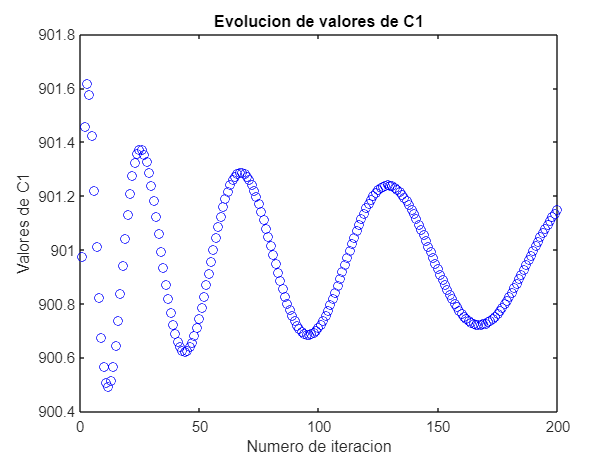

plot(VectorContador,VectorC1,'bo')
title('Evolucion de valores de C1')
ylabel('Valores de C1')
xlabel('Numero de iteracion')

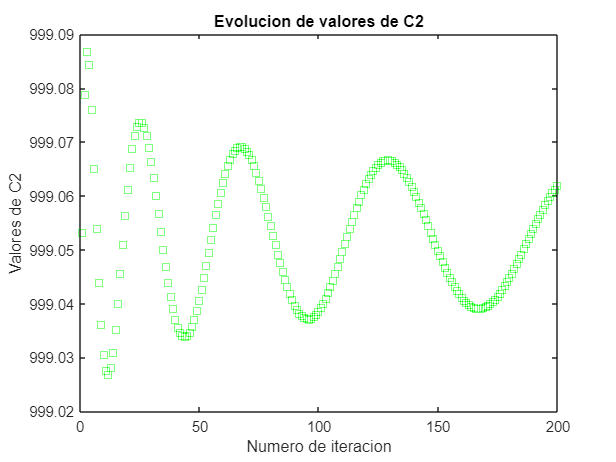


plot(VectorContador,VectorC2,'gs')
title('Evolucion de valores de C2')
ylabel('Valores de C2')
xlabel('Numero de iteracion')

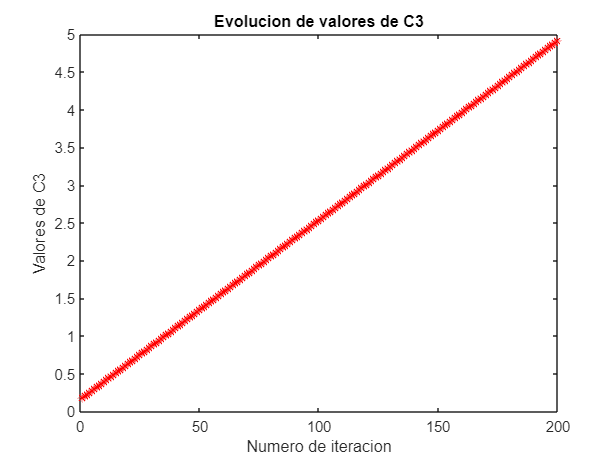


plot(VectorContador,VectorC3,'r*')
title('Evolucion de valores de C3')
ylabel('Valores de C3')
xlabel('Numero de iteracion')

Una ves obtenidas las aproccimaciones de $c_1 ,c_2 \;\mathrm{y}\;c_3$ podemos graficar $\mathrm{T}\left(x,t\right)$

%[xx,tt] = meshgrid(x,t);
%surf(xx,tt,Temp(xx,tt)) ; 
ECM = 0; % inicialización del error cuadratico medio
for i = 1:61
    for j = 1:21
        ECM =  ECM + (Temp(x(j),t(i)) - T(i,j))^2/1281;
    end
end 
ECM

ECM = 545.5628